# Recursive Least Squares estimation

The purpose of this notebook is to show the effectiveness of a recursive algorithm for the estimation of the admittance matrix and to compare it to batch approaches, like LASSO and Ordinary Least Squares (OLS).

## Grid definition

Parameters for the grid are:

- the Laplacian admittance matrix Y

- the load paramenters Il, Pl and Yl

clear all
close all
rng default

Il_bar = [15, 5]';
Yl_bar = [0.01, 0.05]';
Pl_bar = [1200, 800]';
Y = [3 0 -2 -1; 0 2 -1 -1; -2 -1 3 0; -1 -1 0 2];
n = length(Y); % nodes
nl = length(Yl_bar); % loads
ng = n - nl; % generators

## Sample collection

We simulate generator voltages as incorrelated random variables, oscillating around a mean value, and we compute load voltages using power flow equations. Then, we build voltages using the equation I = YV + e. We add a gaussian noise e, with arbitrary variance.

samples = 100;
Vg = normrnd(200, 20, ng, samples);
Vl = zeros(nl, samples);
for i = 1:samples
    Vl_var = sym('Vl_var', [nl, 1]);
    Vl_symb = vpasolve(fl(Vg(:, i), Vl_var, Il_bar, Yl_bar, Pl_bar, Y) == 0, Vl_var);
    [~, i_max] = max(Vl_symb.Vl_var1 + Vl_symb.Vl_var2);
    Vl(:, i) = [Vl_symb.Vl_var1(i_max), Vl_symb.Vl_var2(i_max)]';
end
V = [Vg; Vl];
% V = normrnd(200, 10, n, samples);
I_clean = Y * V;
e = normrnd(0, 0, n, samples); % no noise at the moment
I = I_clean + e;

## Balance check

We check that the power flow equations are always satisfied, in order to certify the goodness of the data

I_check = zeros(nl, samples);
P_check = zeros(nl, samples);
for i = 1:samples
    P_check = fg(Vg(:, i), Vl(:, i), Vg(:, i).*I_clean(1:ng, i), Y);
    I_check = fl(Vg(:, i), Vl(:, i), Il_bar, Yl_bar, Pl_bar, Y);
end
max(abs(P_check))

ans = 1.1823e-11

max(abs(I_check))

ans = 3.2863e-14

## Recursive Least Square

We implement a recursive least square (RLS) estimator for Y, with a forgetting factor.

lambda = 0.9;
Y_0 = 0.1 * ones(n);
P_0 = 100 * eye(n);
Y_hat = [];
Y_hat(:, :, 1) = Y_0;
P_hat = [];
P_hat(:, :, 1) = P_0;
for i = 2:samples
    P_hat(:, :, i) = (1/lambda) * (P_hat(:, :, i-1) - P_hat(:, :, i-1) * V(:, i) * inv(lambda + V(:, i)' * P_hat(:, :, i-1) * V(:, i)) * V(:, i)' * P_hat(:, :, i-1));
    Y_hat(:, :, i) = Y_hat(:, :, i-1) + (I(:, i) - Y_hat(:, :, i-1) * V(:, i)) * V(:, i)' * P_hat(:, :, i);
end

We first check the final results

Y_hat(:, :, end)

ans =     3.0000    0.0001   -1.9997   -1.0004
   -0.0000    1.9998   -1.0005   -0.9993
   -2.0000   -1.0004    2.9987    0.0018
   -1.0000   -0.9995    0.0015    1.9979


P_hat(:, :, end)

ans = 	1.0e+03 *

    0.0004    0.0077    0.0216   -0.0303
    0.0077    0.2024    0.5795   -0.8050
    0.0216    0.5795    1.6602   -2.3052
   -0.0303   -0.8050   -2.3052    3.2013


## Goodness of fit

### Matrix elements

Next, we check the evolution the admittance matrix Y

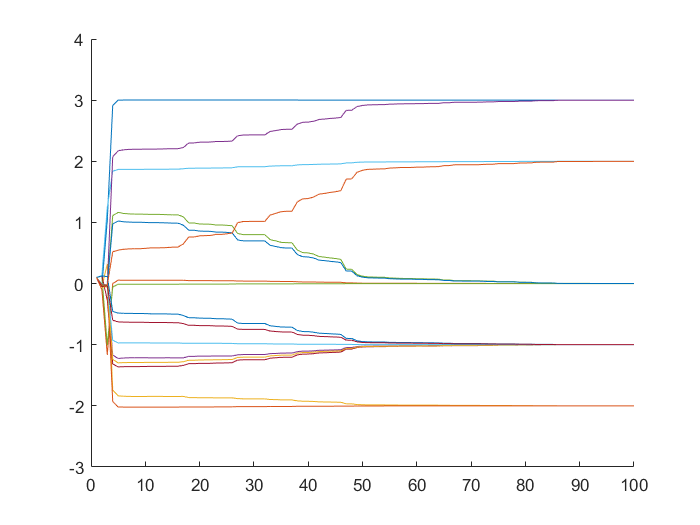

hold on
for i=1:n
    for j=1:n
        plot(1:samples, squeeze(Y_hat(i, j, :)));
    end
end
hold off

### Error metrics

Finally, we resort to some error metrics to evaluate the goodness of fit. Error metrics are the Frobenius norm and the max norm of the matrix $Y_e = \left |Y - \hat Y \right|$.

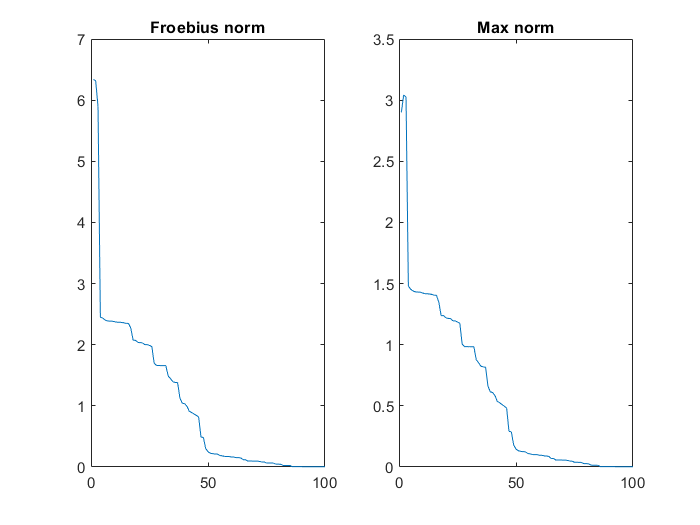

Ye = abs(Y_hat - Y);
froeb_norm = [];
max_norm = [];
for i = 1:samples
    froeb_norm(i) = norm(Ye(:, :, i), 'fro');
    max_norm(i) = max(max(Ye(:, :, i)));
end
subplot(1, 2, 1);
plot(1:samples, squeeze(froeb_norm));
title('Froebius norm');
subplot(1, 2, 2);
plot(1:samples, squeeze(max_norm));
title('Max norm');